#### EX 11-1 监督学习-线性回归

clear; clc; cla;
load carsmall  % 载入MATLAB自带的汽车数据集
% 创建一个表格(tbl)来存储数据，指定列名为 'Weight', 'Acceleration', 和 'MPG'
tbl = table(Weight, Acceleration, MPG, 'VariableNames',...
    {'Weight', 'Acceleration', 'MPG'});
% 利用表格(tbl)中的数据进行线性回归，MPG是因变量，Weight和Acceleration是自变量
lm = fitlm(tbl, 'MPG~Weight+Acceleration')
% 绘制原始数据点，使用星号(*)表示
plot3(Weight, Acceleration, MPG, '*'); 
hold on  % 保持图像，以便在同一图像上添加更多图层
% 设置坐标轴的范围，留出空间以便更好地展示数据和拟合面
axis([min(Weight) - 2, max(Weight) + 2, min(Acceleration) - 1, ...
    max(Acceleration) + 1, min(MPG) - 1, max(MPG) + 1]);
% 设置图像的标题和坐标轴标签
title('二元线性回归'); xlabel('Weight'); ylabel('Acceleration'); zlabel('MPG');
% 生成用于绘制二元拟合面的X轴网格数据，步长为20
X = linspace(min(Weight), max(Weight), 20);
% 生成用于绘制二元拟合面的Y轴网格数据
Y = linspace(min(Acceleration), max(Acceleration), 20);
% 生成X轴和Y轴的网格数据，用于绘制拟合面
[XX, YY] = meshgrid(X, Y);
% 将线性模型的系数从表格格式转换为数组格式
Estimate = table2array(lm.Coefficients);
% 计算拟合面的Z轴数据，根据线性回归模型的系数和网格点
Z = Estimate(1, 1) + Estimate(2, 1) * XX + Estimate(3, 1) * YY;
% 绘制拟合面，使用网格(mesh)的形式
mesh(XX, YY, Z); grid on; hold off;
% 使用模型做出预测举例: 假设某汽车的重量3000，加速度15，要预测它的MPG
predictedMPG = predict(lm, [3000 15]);
% 打印预测的MPG值
fprintf('预测汽车的MPG值为: %.2f\n', predictedMPG);

**EX 11-2 监督学习-逻辑回归**

clear; clc; cla;
% 车辆重量列表
weights = [210 230 250 270 290 310 330 350 370 390 410 430]';
% 对应重量的车辆测试总数
test_counts = [48 42 31 34 31 21 23 23 21 16 17 21]';
% 测试中失败的车辆数
fail_counts = [1 2 0 3 8 8 14 17 19 15 17 21]';
% 计算故障率
failure_rates = fail_counts ./ test_counts;
% 使用glmfit进行逻辑回归。response是二列矩阵，第一列为成功次数，第二列为总观测次数
[logit_coeffs, ~] = ...
    glmfit(weights, [fail_counts test_counts], 'binomial', 'link', 'logit');
% 使用glmval根据拟合模型估计故障率
estimated_rates = glmval(logit_coeffs, weights, 'logit');
% 绘制原始数据点和logistic回归曲线
plot(weights, failure_rates, 'bs', weights, estimated_rates, 'r-');
xlabel('重量'); ylabel('故障率');
legend('实际数据', '逻辑回归拟合');
% 假设我们要预测的新车辆重量
new_weights = [320 340 360]';
% 使用拟合的logistic回归模型进行预测
predicted_failure_rates = glmval(logit_coeffs, new_weights, 'logit');
% 显示预测结果
for i = 1:length(new_weights)
    fprintf('重量为 %d 的车辆预测故障率为: %.4f\n',...
        new_weights(i), predicted_failure_rates(i));
end

**EX 11-3 监督学习-分类**

clear; clc;
fishertable = readtable('fisheriris.csv')
% 此处操作在App中
% 定义3组测试数据的特征值
SepalLength = [7.5; 4.6; 5.7];
SepalWidth = [2.9; 3.2; 2.7];
PetalLength = [5.9; 1.4; 4.6];
PetalWidth = [1.6; 0.2; 1.3];
Species = ["virginica"; "setosa"; "versicolor"];
% 创建一个新的表格，列名与fishertable相同
testData = table(SepalLength, SepalWidth, PetalLength, PetalWidth, Species);
% 显示测试数据
disp(testData);


**EX 11-4 无监督学习-聚类-K均值法**

clear; clc; cla;
% 1. 读取数据
fishertable = readtable('fisheriris.csv');
% 2. 提取特征数据
features = fishertable{:, 1:4};
% 3. 进行K均值聚类
k = 3;
[idx, C] = kmeans(features, k);
% 4. 可视化聚类结果
gscatter(features(:,1), features(:,2), idx);
title('K-Means Clustering of Fisher Iris Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Cluster 1','Cluster 2','Cluster 3');

**EX 11-5 无监督学习-降维-主成分分析**

clear; clc; cla;
% 1. 读取数据
fishertable = readtable('fisheriris.csv');
% 2. 提取特征
features = fishertable{:, 1:4};
% 3. 执行PCA
[coeff, score, latent] = pca(features);
% 4. 选择主成分
reducedDimension = score(:, 1:2);
% 5. 可视化结果
scatter(reducedDimension(:,1), reducedDimension(:,2));
title('PCA的Fisher鸢尾数据');
xlabel('第一主成分');
ylabel('第二主成分');

**EX 11-6 强化学习**

clear; clc; cla;
% 环境初始化
gridSize = 4;
goalState = [4, 4];
startState = [1, 1];
obstacles = [2, 2; 3, 3];
numStates = gridSize * gridSize;
numActions = 4; % 上下左右
% Q表初始化
Q = zeros(numStates, numActions);
% 学习参数
alpha = 0.1; % 学习率
gamma = 0.9; % 折扣因子
epsilon = 0.1; % 探索概率
numEpisodes = 500; % 训练回合数
% 学习过程
for episode = 1:numEpisodes
    state = startState;
    isTerminal = false;
    while ~isTerminal
        % ϵ-贪婪策略选择动作
        if rand < epsilon
            action = randi(numActions);
        else
            [~, action] = max(Q(state(1) + (state(2) - 1) * gridSize, :));
        end
        % 执行动作，观察新状态和奖励
        [newState, reward, isTerminal] = ...
            stepFunction(state, action, goalState, obstacles, gridSize);
        % Q表更新
        currentStateIndex = state(1) + (state(2) - 1) * gridSize;
        newStateIndex = newState(1) + (newState(2) - 1) * gridSize;
        bestFutureQ = max(Q(newStateIndex, :));
        Q(currentStateIndex, action) = Q(currentStateIndex, action) + ...
            alpha * (reward + gamma * bestFutureQ - Q(currentStateIndex, action));
        % 迁移到新状态
        state = newState;
    end
end
% 测试训练好的策略
state = startState;
path = state;
while ~isequal(state, goalState)
    [~, action] = max(Q(state(1) + (state(2) - 1) * gridSize, :));
    [state, ~, ~] = stepFunction(state, action, goalState, obstacles, gridSize);
    path = [path; state];
end
% 展示路径
disp('Learned path to goal:');

Learned path to goal:


disp(path);

     1     1
     1     2
     1     3
     1     4
     2     4
     3     4
     4     4



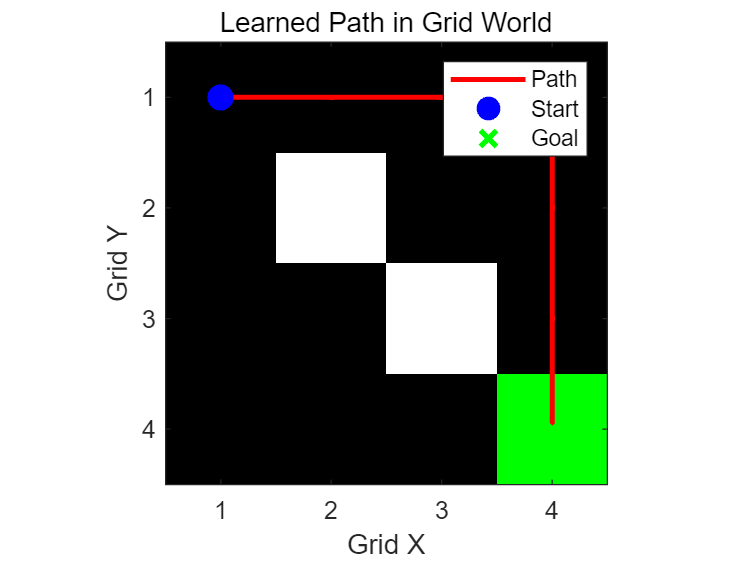

% 绘制网格地图和路径
map = zeros(gridSize); % 初始化地图
map(sub2ind([gridSize, gridSize], obstacles(:,1), obstacles(:,2))) = -1; % 设置障碍物位置
map(sub2ind([gridSize, gridSize], goalState(1), goalState(2))) = 1; % 设置目标位置
% 绘制网格地图
imagesc(map); % 绘制地图
colormap([1 1 1; 0 0 0; 0 1 0]); % 白色为可行走区域，黑色为障碍物，绿色为目标点
hold on; % 保持当前图形，用于在上面绘制其他图形元素
% 绘制路径
pathIndex = sub2ind([gridSize, gridSize], path(:,1), path(:,2));
[pathY, pathX] = ind2sub([gridSize, gridSize], pathIndex);
plot(pathX, pathY, 'r.-', 'LineWidth', 2); % 用红色线连起所有点，'.'表示点的样式
% 添加起点和终点标记
plot(startState(2), startState(1), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b'); % 蓝色圆圈表示起点
plot(goalState(2), goalState(1), 'gx', 'MarkerSize', 10, 'LineWidth', 2); % 绿色叉号表示目标点
% 设置坐标轴范围和标签
axis square;
set(gca, 'XTick', 1:gridSize, 'YTick', 1:gridSize);
xlabel('Grid X'); ylabel('Grid Y');
title('Learned Path in Grid World');
% 显示图例
legend('Path', 'Start', 'Goal');
hold off; % 释放图形，之后的绘图命令将创建新的图形元素

function [newState, reward, isTerminal] = stepFunction(state, action, goalState, obstacles, gridSize)
% stepFunction是环境的动作执行函数，返回新状态、奖励和是否达到终点
% 根据动作计算新状态
switch action
    case 1 % 上
        newState = [state(1), max(state(2) - 1, 1)];
    case 2 % 下
        newState = [state(1), min(state(2) + 1, gridSize)];
    case 3 % 左
        newState = [max(state(1) - 1, 1), state(2)];
    case 4 % 右
        newState = [min(state(1) + 1, gridSize), state(2)];
end
% 检查新状态是否为障碍物或目标
if isequal(newState, goalState)
    reward = 100;
    isTerminal = true;
elseif any(ismember(obstacles, newState, 'rows'))
    reward = -100;
    isTerminal = true;
else
    reward = -1;
    isTerminal = false;
end
end